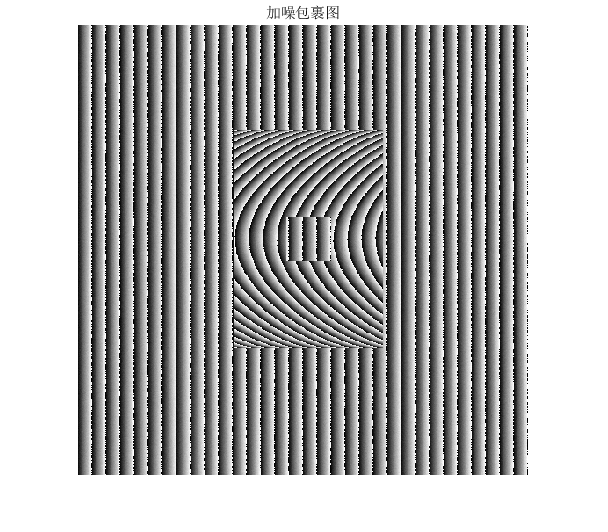

%%此部分获得高频和低频之间的K值%%%%
clc
clear all
clf


%%%通过比较K取整和不取整的结果，最后决定对k不取整，这样才能恢复准确度较高的相位


phi_wrapped_high1=load('E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new\phi_wrapped_high\1025.mat');

phi_wrapped_high=phi_wrapped_high1.phi_wrapped_high;
figure;
imshow(phi_wrapped_high,[]);
title('加噪包裹图')

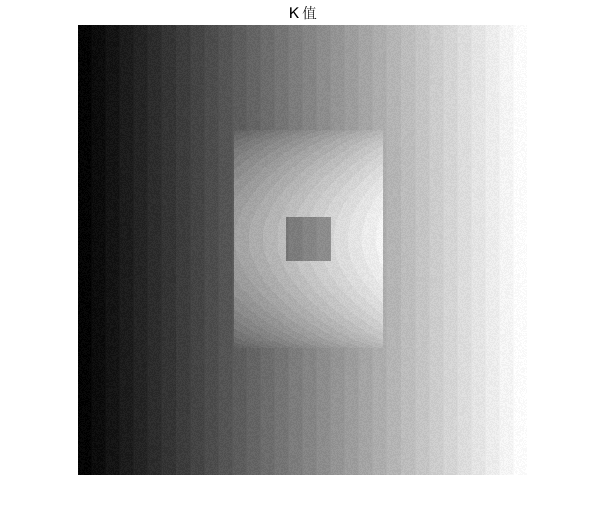



phi_unwrapped_no_noisy1=load('E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new\phi_unwrapped_no_noisy\1025.mat','phi_unwrapped');
phi_unwrapped_no_noisy=phi_unwrapped_no_noisy1.phi_unwrapped;
get_k=round((phi_unwrapped_no_noisy-phi_wrapped_high)/(2*pi));
% get_k=(phi_unwrapped_no_noisy-phi_wrapped_high)/(2*pi);
figure;
imshow(get_k,[]);
title('K 值')

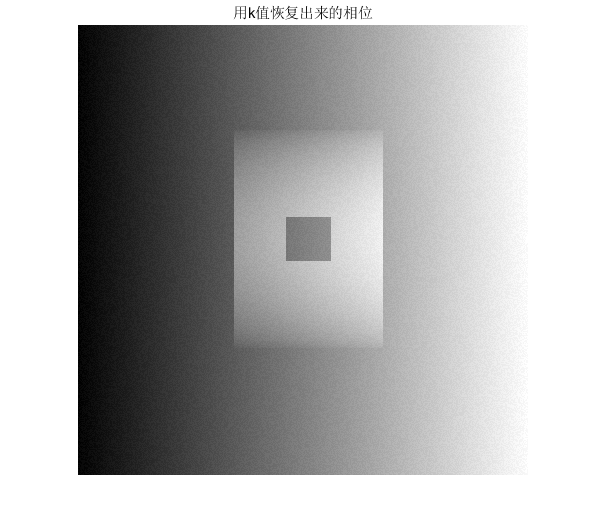


r_unwrapped=phi_wrapped_high+get_k*2*pi;
figure;
imshow(r_unwrapped,[]);
title('用k值恢复出来的相位')

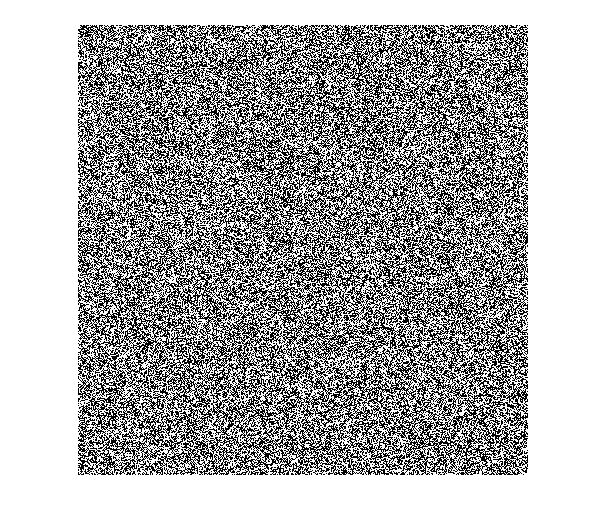

r_error=phi_unwrapped_no_noisy-r_unwrapped;
% r_error = wdenoise2(r_error);%小波去噪
figure;
imshow(r_error,[]);

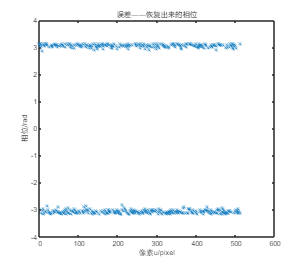

plot(r_error(350,:),'*');xlabel('像素u/pixel');ylabel('相位/rad'); 
title('误差——恢复出来的相位')

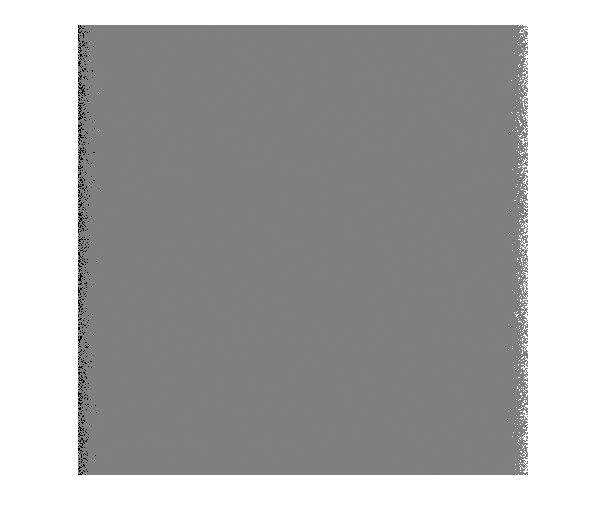


phi_unwrapped1=load('E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new\phi_unwrapped\1025.mat','phi_unwrapped');
phi_unwrapped=phi_unwrapped1.phi_unwrapped;
B=phi_unwrapped_no_noisy-phi_unwrapped;
figure;
imshow(B,[]);

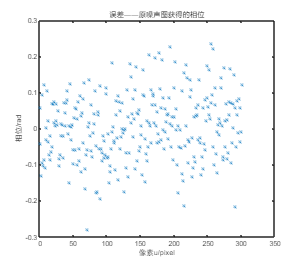

plot(B(200,100:400),'*');xlabel('像素u/pixel');ylabel('相位/rad'); 
title('误差——原噪声图获得的相位')